for i=1:11
    valid_amp_idx = find(meta_ampsweep_jitter(i).stim_amp > 0.01);
    
    meta_ampsweep_jitter(i).valid_amp = meta_ampsweep_jitter(i).stim_amp(valid_amp_idx);
    meta_ampsweep_jitter(i).valid_jitter_vals = meta_ampsweep_jitter(i).I_spike_jitter(valid_amp_idx);
    
end




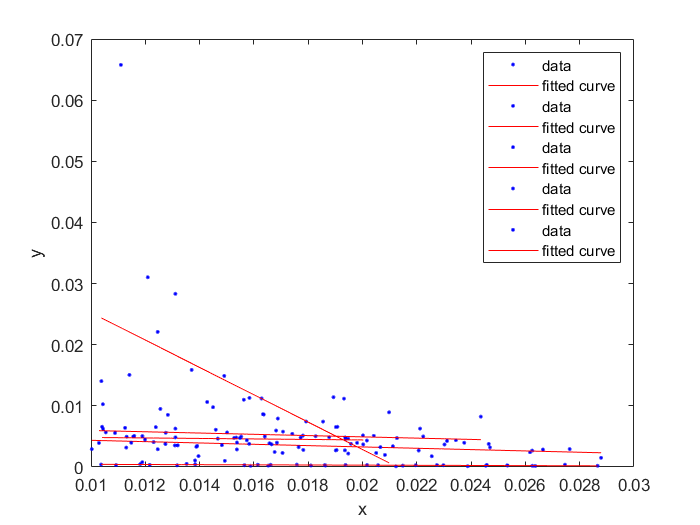

figure;
cmp = parula(5);
for i=1:5
%         figure;
%     scatter(meta_ampsweep_jitter(i).valid_amp, meta_ampsweep_jitter(i).valid_jitter_vals, 10, cmp(i,:),"filled");
        [f, gof] = fit((meta_ampsweep_jitter(i).valid_amp)', (meta_ampsweep_jitter(i).valid_jitter_vals)', 'poly1');
        plot(f,meta_ampsweep_jitter(i).valid_amp, meta_ampsweep_jitter(i).valid_jitter_vals);
    %     plot(f);
    hold on;
    
end


for i = 1:5
    
    trim_point = mod(length(meta_ampsweep_jitter(i).valid_amp),3);
    amp_vals = meta_ampsweep_jitter(i).valid_amp(1:end-trim_point);
    jitter_vals = (meta_ampsweep_jitter(i).valid_jitter_vals(1:end-trim_point))*1000;
    
    mean_amp_vals = mean(reshape(amp_vals,[],length(amp_vals)/3),1);
    jitter_vals_reshape = reshape(jitter_vals,[],length(amp_vals)/3);
    
    figure;
    boxplot(jitter_vals_reshape, (round(mean_amp_vals, 3))*1000, "BoxStyle","outline","PlotStyle","compact",'MedianStyle',"line", "Symbol",'o',"OutlierSize",0.2);
    
    xlabel('Amplitude (um)');
    ylabel('First spike jitter (ms)');
    ylim([0 inf]);   
    box off;
    
end